%% Biosignal Processing - Lab 2 Part 1
%% Spectral estimation for cardiovascular signals

clear; close all; clc;

%% Task 0.0 - Load data

data = load('heart_data.mat');

d1_rr = data.data1.RR;
d1_ap = data.data1.arterial_pressure;
d1_ilv = data.data1.ILV;

d2_rr = data.data2.RR;
d2_ap = data.data2.arterial_pressure;
d2_ilv = data.data2.ILV;

% Signal lengths
Nd1_rr = length(d1_rr);
Nd2_rr = length(d2_rr);


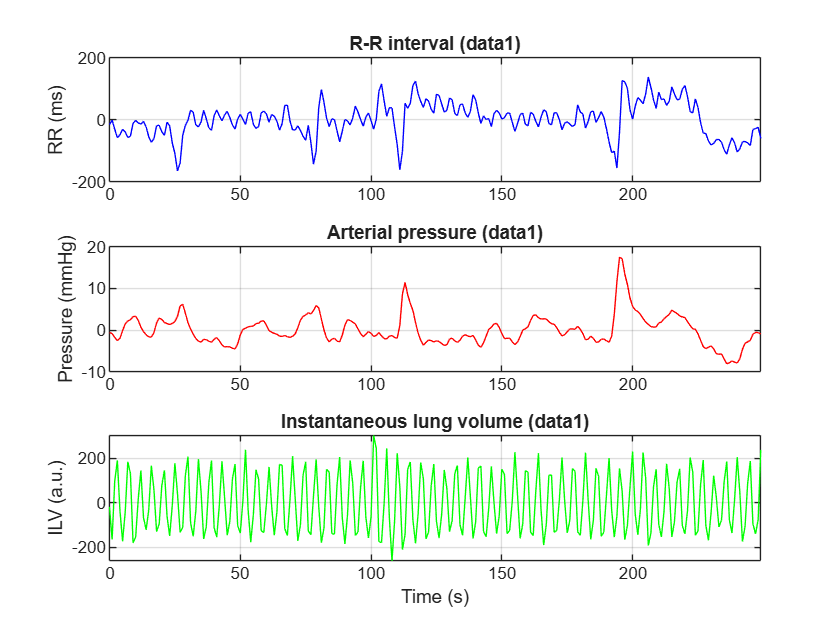

%% Task 1.1 - Plot data1
%% Patient in resting state
Fs = 1;                         
t = (0:Nd1_rr-1)/Fs;

%% Plot all signals
figure;

subplot(3,1,1)
plot(t, d1_rr, 'b')
grid on
title('R-R interval (data1)')
ylabel('RR (ms)')
xlim([0 t(end)])

subplot(3,1,2)
plot(t, d1_ap, 'r')
grid on
title('Arterial pressure (data1)')
ylabel('Pressure (mmHg)')
xlim([0 t(end)])

subplot(3,1,3)
plot(t, d1_ilv, 'g')
grid on
title('Instantaneous lung volume (data1)')
xlabel('Time (s)')
ylabel('ILV (a.u.)')
xlim([0 t(end)])

%% my_AR_spectrum function

function [Phi,freq_grid] = my_AR_spectrum(x,P,fs,freq_grid)

x = x(:);

if nargin<4 || isempty(freq_grid)
    if nargin<3 || isempty(fs)
        fs = 1;
    end
    N_freq = 1e4;
    freq_grid = linspace(0,fs/2,N_freq)';
end
freq_grid = freq_grid(:);
if max(freq_grid)>fs/2
    error('The maximum allowed frequency is fs/2')
end

ar_pol = aryule(x,P);
%ar_pol = arburg(x,P);
%ar_pol = arcov(x,P);
sigma2_est = var(filter(ar_pol,1,x));

omega_grid = 2*pi*freq_grid/fs;

freq_mat = exp(1i*(0:P)'*omega_grid');

Phi = sigma2_est./abs(ar_pol(:)'*freq_mat).^2;
Phi = Phi(:);
end


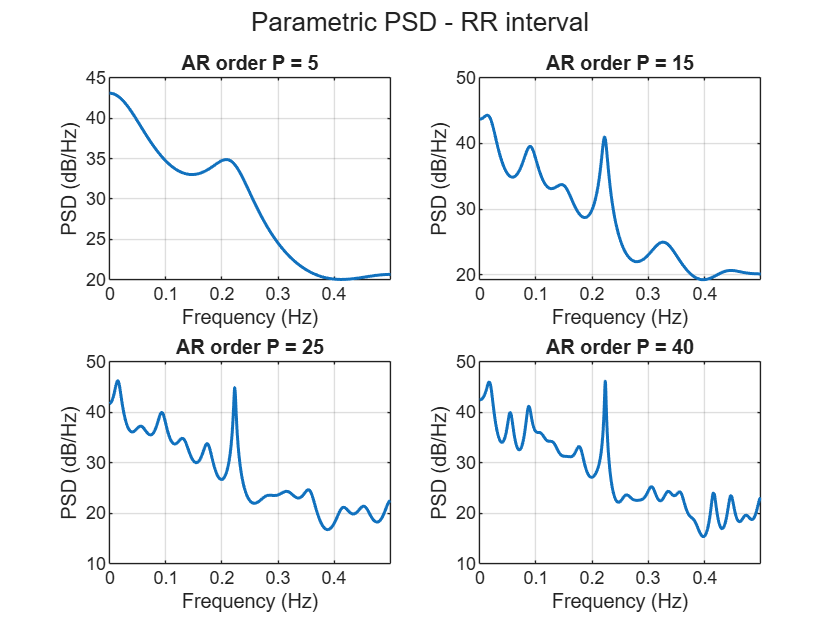

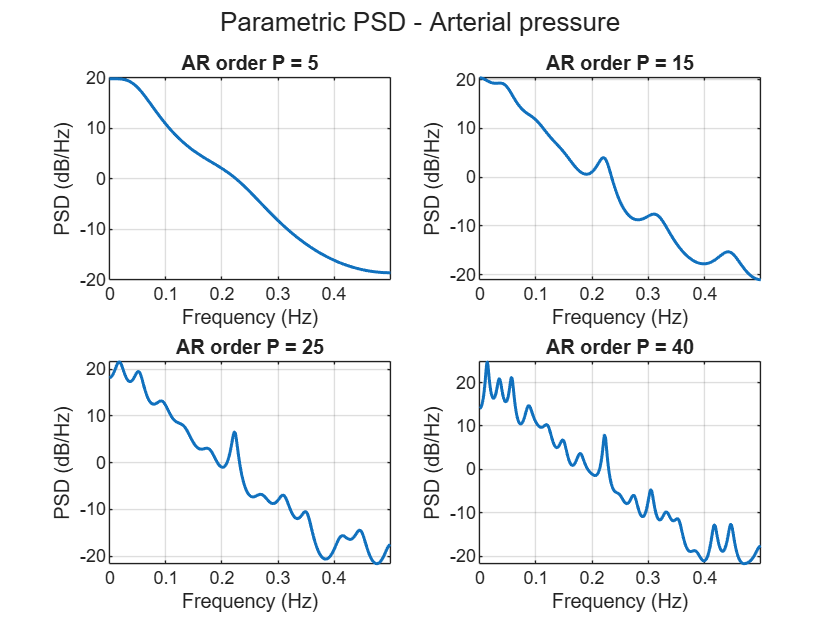

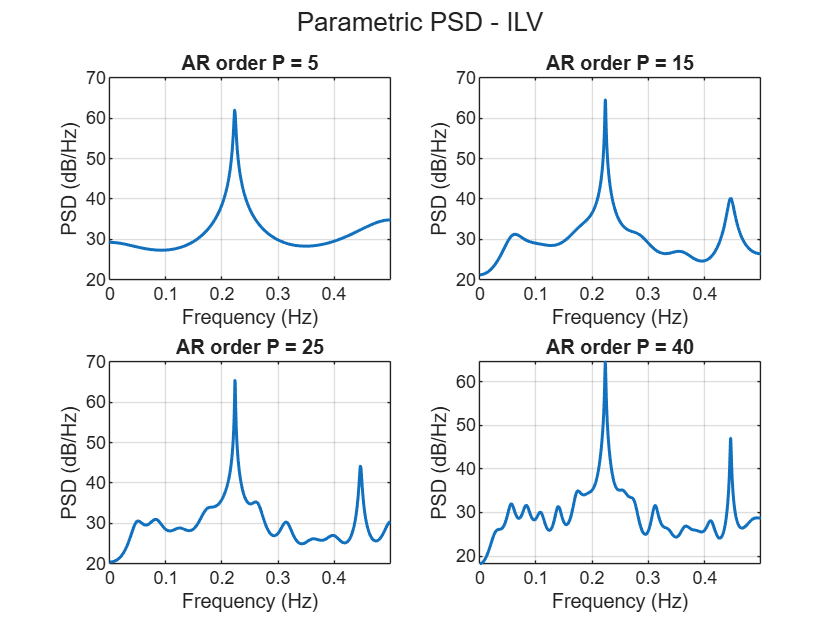

%% Task 1.2 - Parametric spectral estimation
orders = [5 15 25 40];
freq_grid = linspace(0, Fs/2, 1000);   

signals = {d1_rr, d1_ap, d1_ilv};
signal_names = {'RR interval', 'Arterial pressure', 'ILV'};

AIC = zeros(4,3);
MDL = zeros(4,3);

for s = 1:3

    y = signals{s};

    figure
    sgtitle(['Parametric PSD - ' signal_names{s}])

    for p = 1:length(orders)

        P = orders(p);
        N = length(y);

        % Compute AR spectrum
        [Phi, freq] = my_AR_spectrum(y, P, Fs, freq_grid);

        ar_pol = aryule(y, P);
        sigma2 = var(filter(ar_pol, 1, y));
        
        AIC(p,s) = N * log(sigma2) + 2 * P;
        MDL(p,s) = N * log(sigma2) + P * log(N);

        subplot(2,2,p)
        plot(freq, 10*log10(Phi), 'LineWidth', 1.5)
        grid on

        title(['AR order P = ' num2str(P)])
        xlabel('Frequency (Hz)')
        ylabel('PSD (dB/Hz)')
        xlim([0 0.5])       
    end

end


%% Find optimal order for each signal

[min_AIC, idx_AIC] = min(AIC, [], 1);   % Minimum in each column
[min_MDL, idx_MDL] = min(MDL, [], 1);

p0_AIC = orders(idx_AIC);
p0_MDL = orders(idx_MDL);

disp('Optimal AR orders using AIC:')

Optimal AR orders using AIC:


disp(table(signal_names', p0_AIC', min_AIC', ...
    'VariableNames', {'Signal','Order','AIC'}))

           Signal            Order      AIC  
    _____________________    _____    _______

    {'RR interval'      }     25       1654.9
    {'Arterial pressure'}      5      -110.23
    {'ILV'              }     25       1774.5




disp('Optimal AR orders using MDL:')

Optimal AR orders using MDL:


disp(table(signal_names', p0_MDL', min_MDL', ...
    'VariableNames', {'Signal','Order','MDL'}))

           Signal            Order      MDL  
    _____________________    _____    _______

    {'RR interval'      }      5       1702.1
    {'Arterial pressure'}      5      -92.628
    {'ILV'              }     15       1829.2



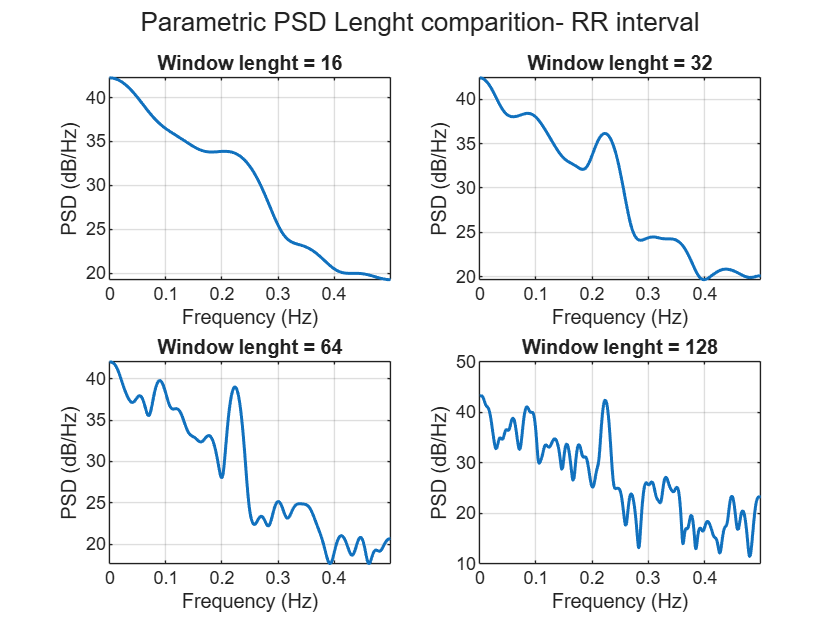

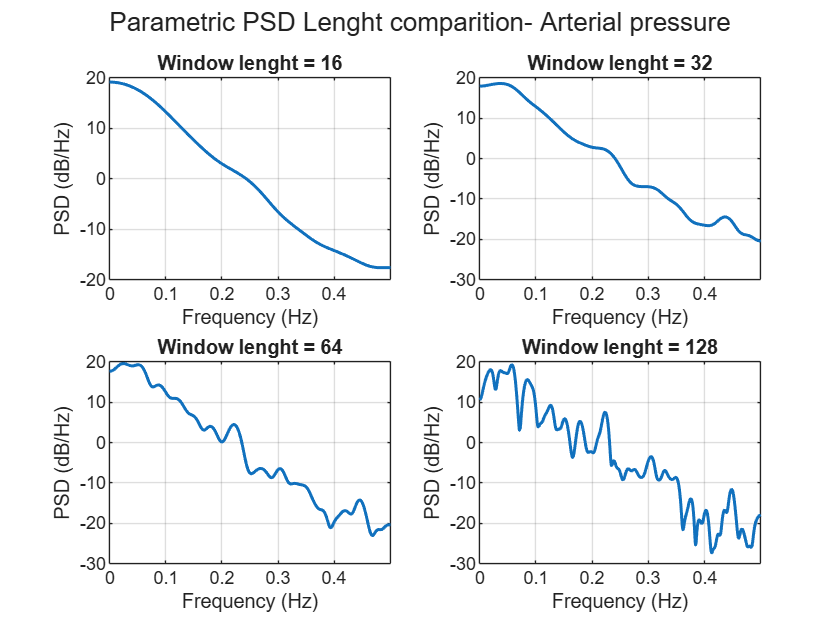

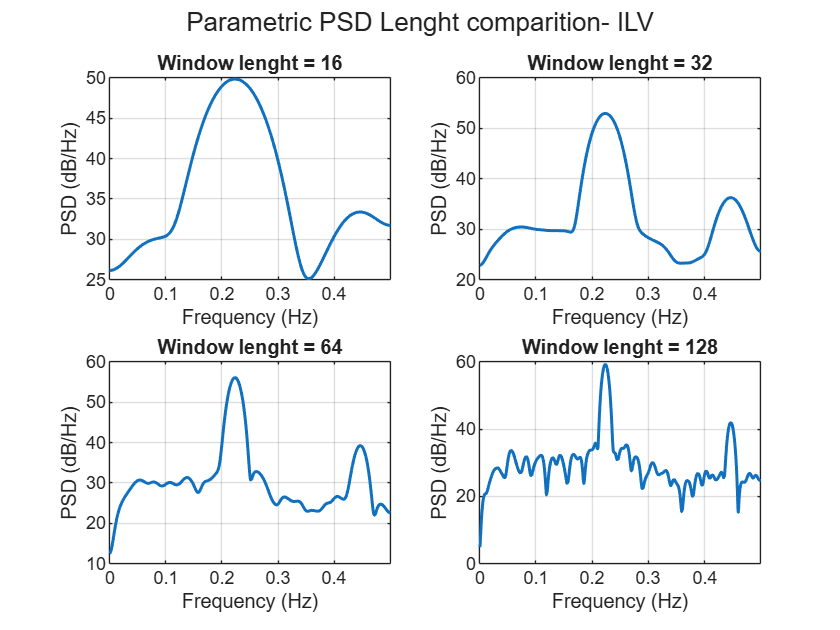

%% Task 1.3 - Non-Parametric spectral estimation
wlenghts = [16 32 64 128];
woverlap = [0 0.25 0.5 0.75];

freq_grid = linspace(0, Fs/2, 1000);   

signals = {d1_rr, d1_ap, d1_ilv};
signal_names = {'RR interval', 'Arterial pressure', 'ILV'};

%% Window length comparison
for s = 1:3

    y = signals{s};

    figure
    sgtitle(['Parametric PSD Lenght comparition- ' signal_names{s}])

    for p = 1:length(wlenghts)

        window = wlenghts(p);
        noverlap = window/2;

        % Compute pwelch
        [Phi, freq] = pwelch(y, window, noverlap, freq_grid,Fs);

        subplot(2,2,p)
        plot(freq, 10*log10(Phi), 'LineWidth', 1.5)
        grid on

        title(['Window lenght = ' num2str(window)])
        xlabel('Frequency (Hz)')
        ylabel('PSD (dB/Hz)')
        xlim([0 0.5])       
    end

end

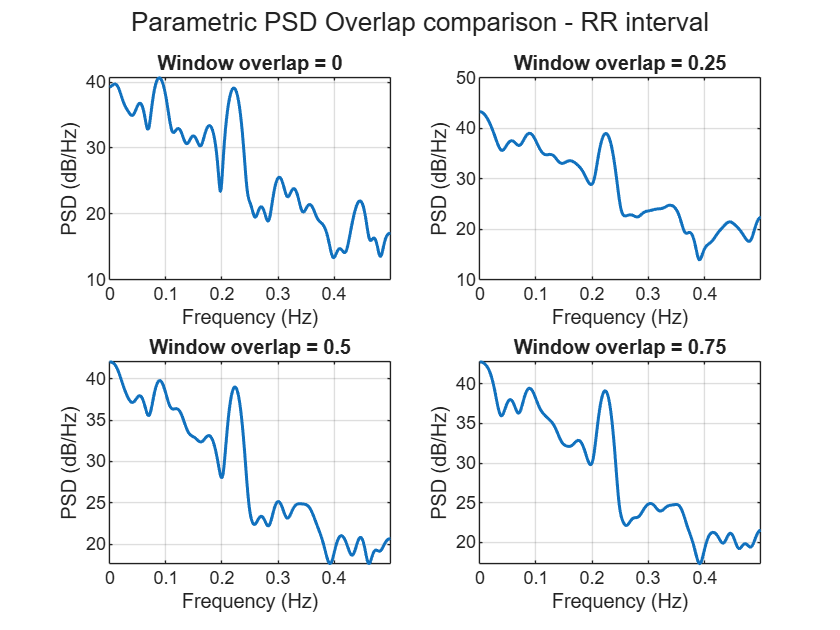

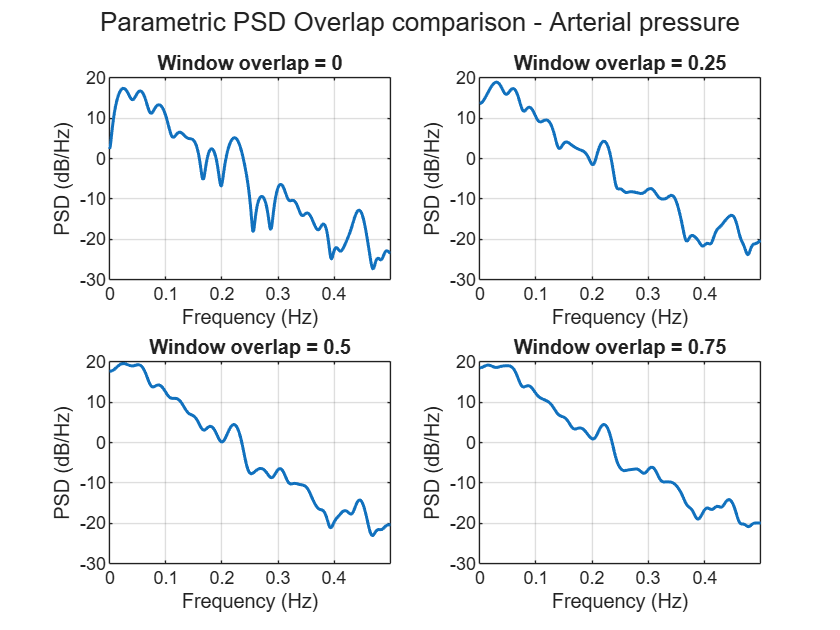

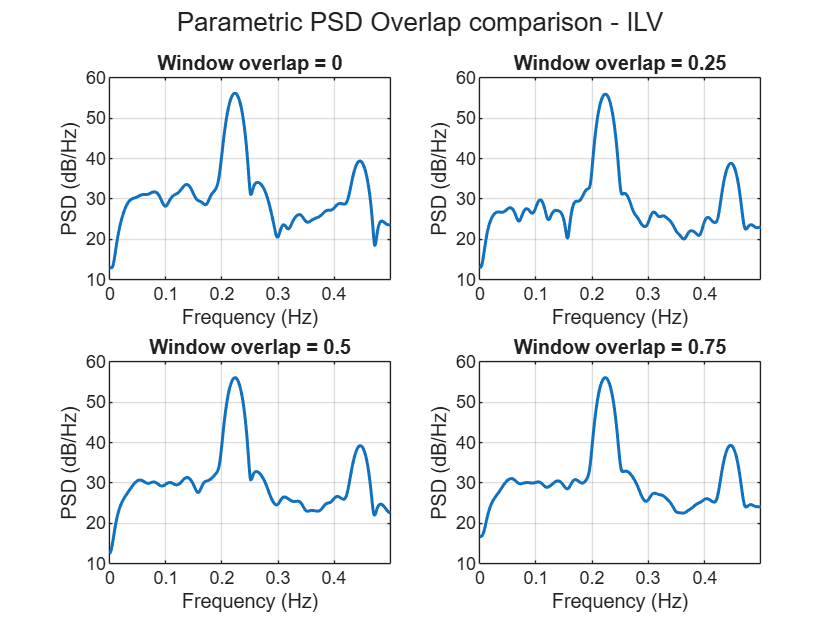

%% Window overlap comparison
for s = 1:3

    y = signals{s};

    figure
    sgtitle(['Parametric PSD Overlap comparison - ' signal_names{s}])

    for p = 1:length(woverlap)

        window = 64;
        noverlap = round(window*woverlap(p));

        % Compute pwelch
        [Phi, freq] = pwelch(y, window, noverlap, freq_grid,Fs);

        subplot(2,2,p)
        plot(freq, 10*log10(Phi), 'LineWidth', 1.5)
        grid on

        title(['Window overlap = ' num2str(woverlap(p))])
        xlabel('Frequency (Hz)')
        ylabel('PSD (dB/Hz)')
        xlim([0 0.5])       
    end

end

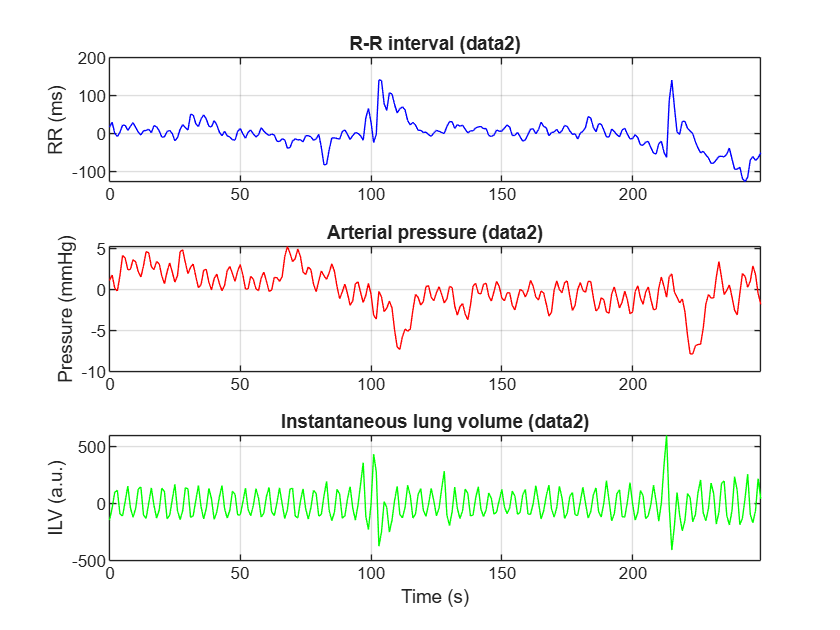


%% Task 2.1 - Plot data2
%% Patient after alcohol intake
Fs = 1;                         
t = (0:Nd2_rr-1)/Fs;

%% Plot all signals
figure;

subplot(3,1,1)
plot(t, d2_rr, 'b')
grid on
title('R-R interval (data2)')
ylabel('RR (ms)')
xlim([0 t(end)])

subplot(3,1,2)
plot(t, d2_ap, 'r')
grid on
title('Arterial pressure (data2)')
ylabel('Pressure (mmHg)')
xlim([0 t(end)])

subplot(3,1,3)
plot(t, d2_ilv, 'g')
grid on
title('Instantaneous lung volume (data2)')
xlabel('Time (s)')
ylabel('ILV (a.u.)')
xlim([0 t(end)])

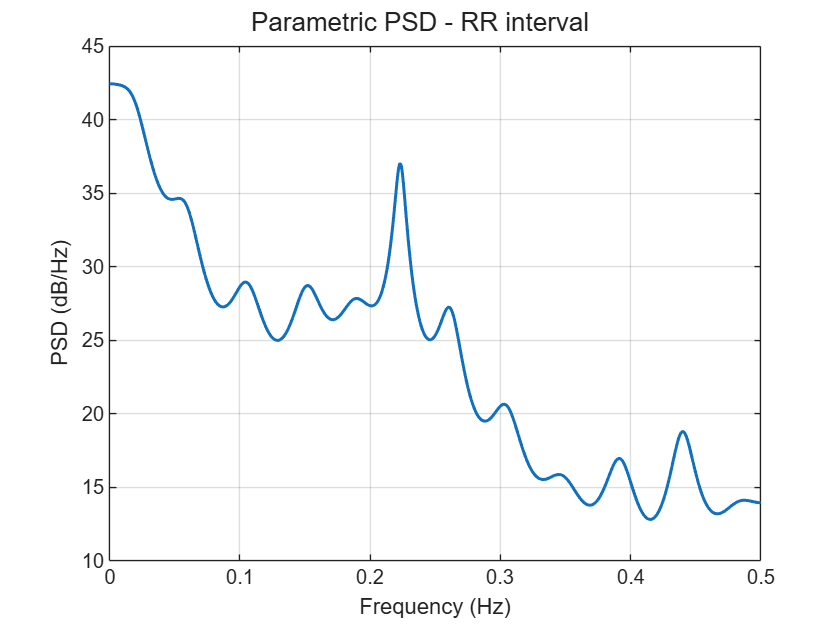

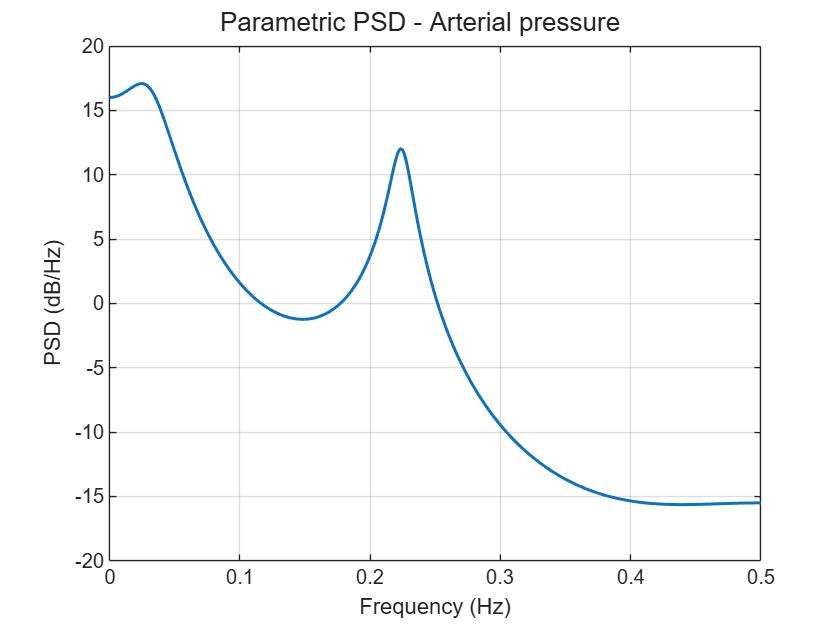

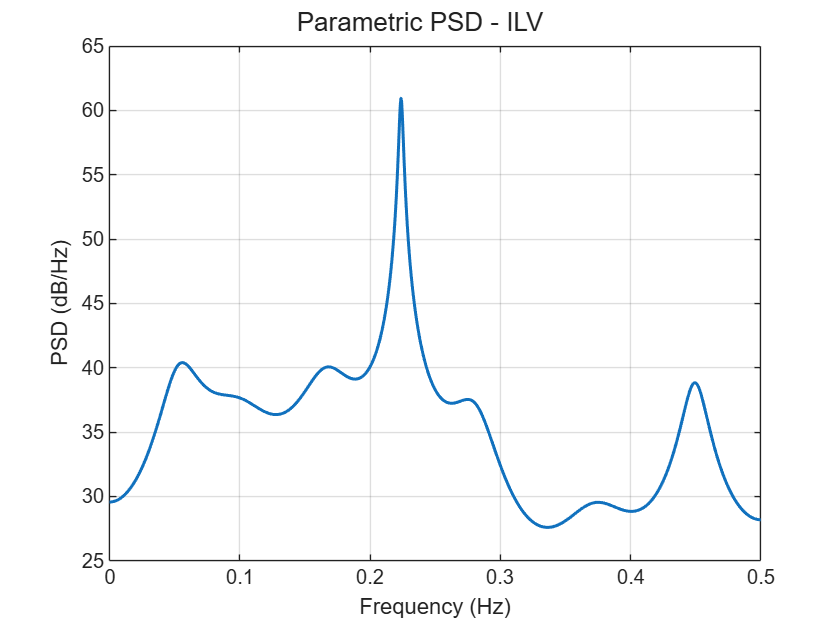

%% Task 2.2 - Parametric spectral estimation
orders = [25 5 15];
freq_grid = linspace(0, Fs/2, 1000);   

signals = {d2_rr, d2_ap, d2_ilv};
signal_names = {'RR interval', 'Arterial pressure', 'ILV'};

for s = 1:3

    y = signals{s};

    figure
    sgtitle(['Parametric PSD - ' signal_names{s}])

    P = orders(s);

    % Compute AR spectrum
    [Phi, freq] = my_AR_spectrum(y, P, Fs, freq_grid);

    
    plot(freq, 10*log10(Phi), 'LineWidth', 1.5)
    grid on

    xlabel('Frequency (Hz)')
    ylabel('PSD (dB/Hz)')
    xlim([0 0.5])   
end